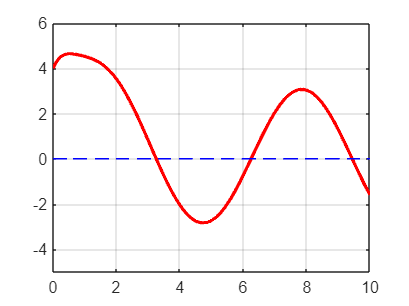

f = @(x)3.*sin(x) + 4 ./ (x.^2 + 1);
% disp(f([4,3]));
% disp([f(4), f(3)]);

dom = linspace(0, 10, 1000);
fx = f(dom);
% whos % print vars

z = @(x)0 * x; % 0 is not valid
zx = z(dom);

figure(1);
plot(dom, fx, "red", LineWidth=2);
hold on;
plot(dom, zx, "blue--");
hold off;
axis([0, 10, -5, 6]);
ax = gca;
ax.YGrid = 'on';
ax.XGrid = 'on';

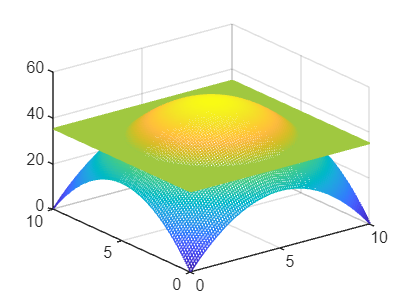

domX = linspace(0, 10, 100);
domY = linspace(0, 10, 100);

n = length(domX);
F = zeros(n,n);
G = zeros(n,n);

f = @(x, y)x*(10 - x) + y*(10 - y);

const = 35;

for i = 1:n
    for j = 1:n
        F(i,j) = f(domX(i), domY(j));
        G(i,j) = const;
    end
end

mesh(domX, domY, F);
hold on;
mesh(domX, domY, G);
hold off;